## Amplitude Demodulation using Envelope Detector

% Clear workspace and close figures
clear all;
close all;

% Load the audio file
audioFile = 'videoplayback.wav';
[x, fs] = audioread(audioFile);

% Play the audio file
disp('Playing the original audio...'); % Add a message to the console

Playing the original audio...


sound(x, fs); % Play the audio
pause(length(x) / fs); % Pause to allow time for audio playback (adjust the duration as needed)
disp('Audio playback completed.'); % Display a completion message

Audio playback completed.


% Split audio into left and right channels
l = x(:, 1); % Left audio
r = x(:, 2); % Right audio

% Initialize the demodulated output array
demod = zeros(size(x));

% Define the time vector
t = (0:length(x) - 1) / fs;

% Modulation indices for under, critically, and over modulation
mu = [0.5, 1, 2];

% Initialize the carrier frequency
fc = 1e6;

% Generate the carrier wave and reshape it to match the audio signal
c = 2 * cos(2 * pi * fc * t);
c = reshape(c, size(l));

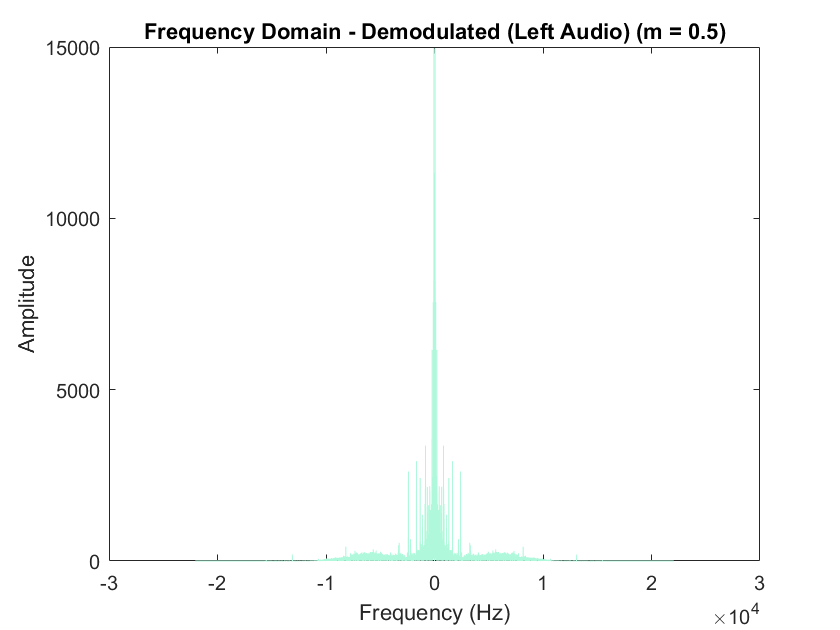

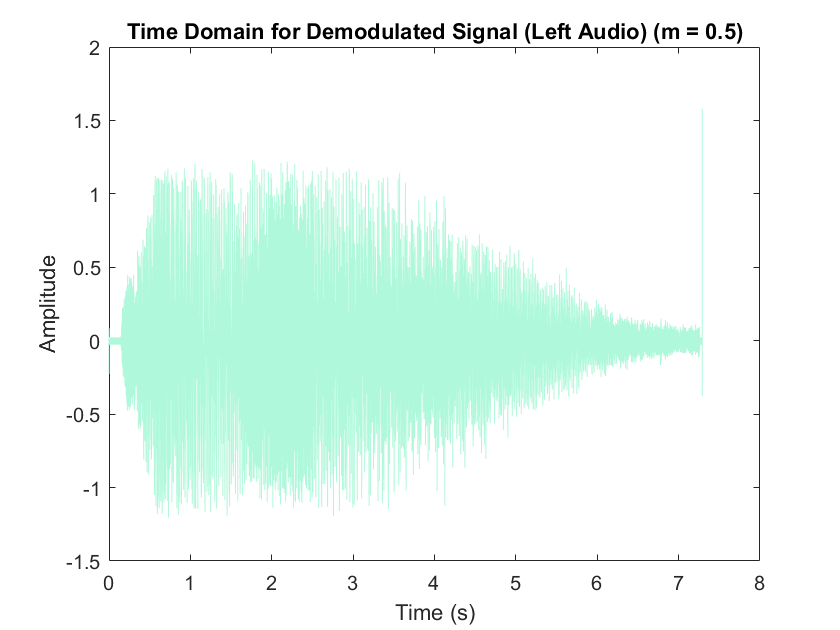

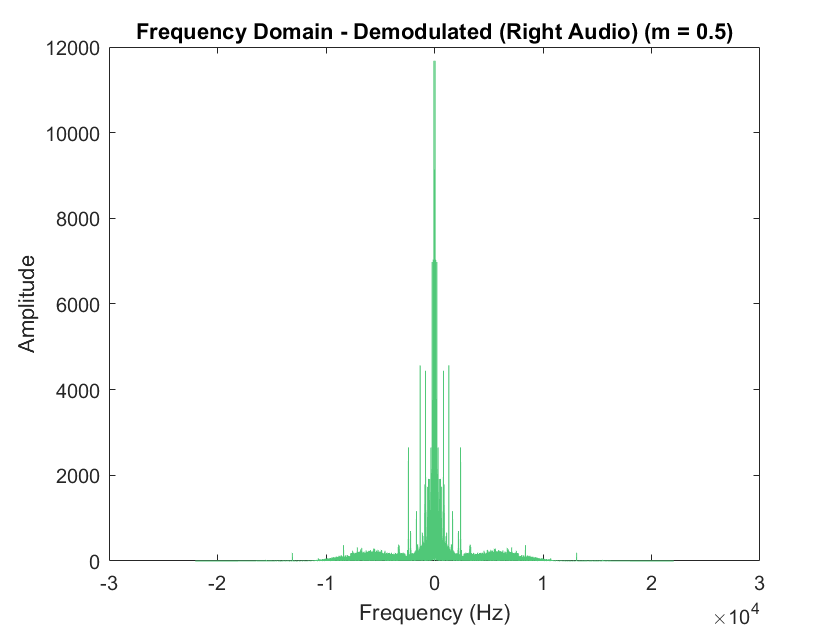

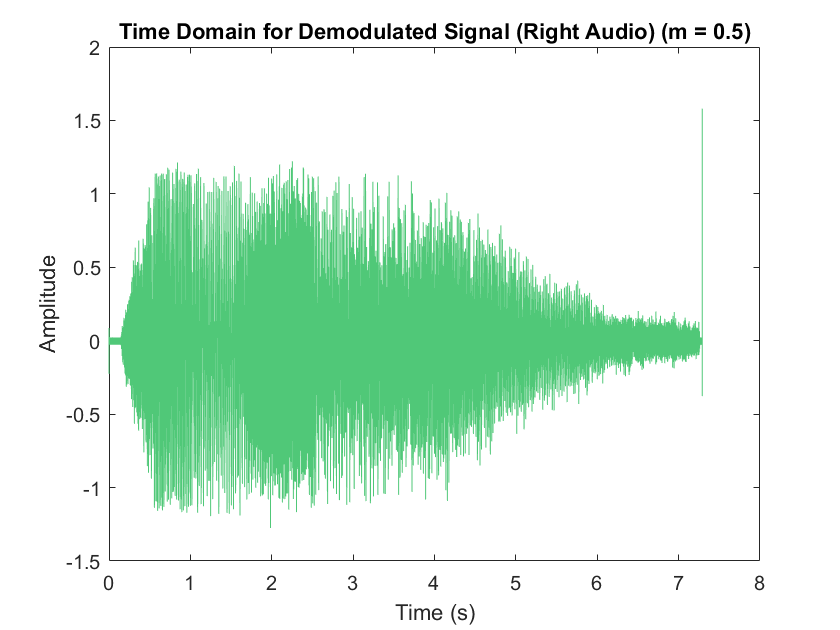

Playing demodulated audio (m = 0.5)


Audio Playback Completed.


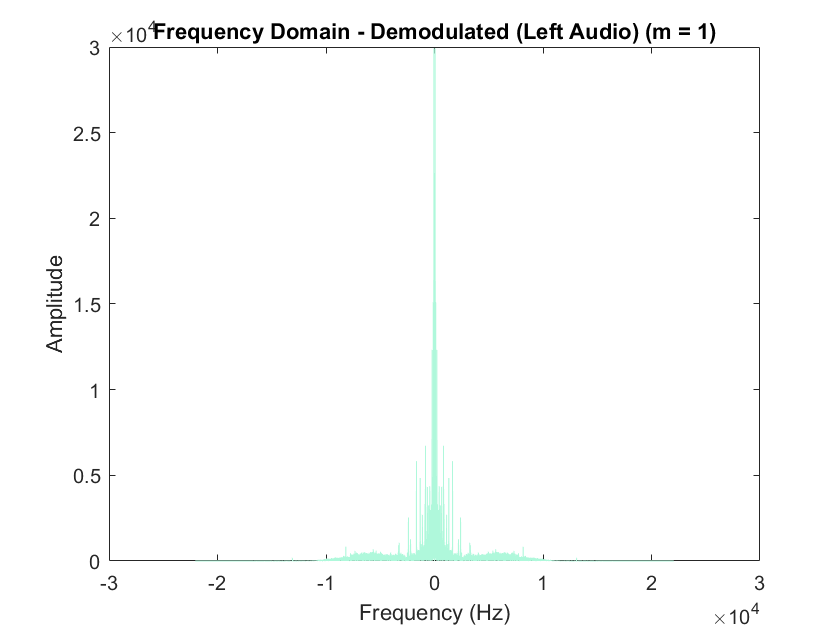

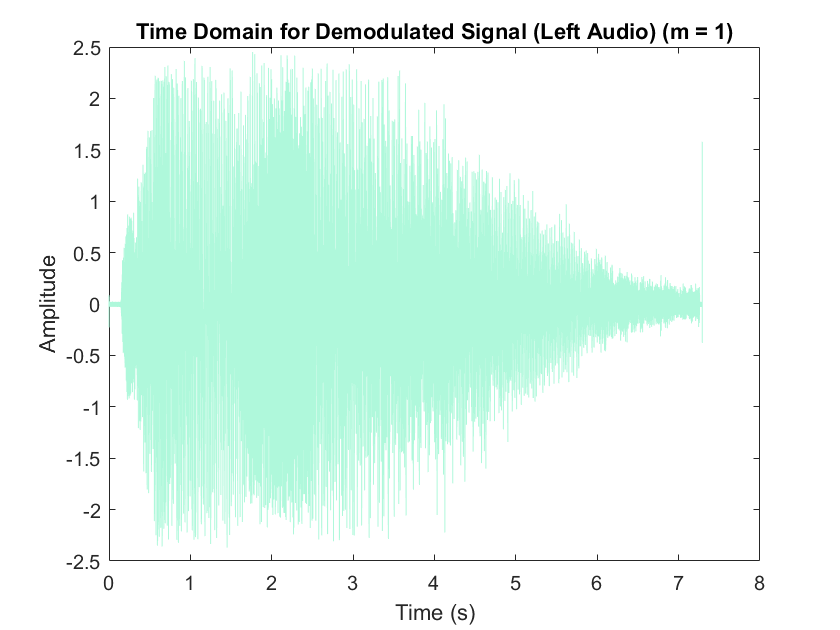

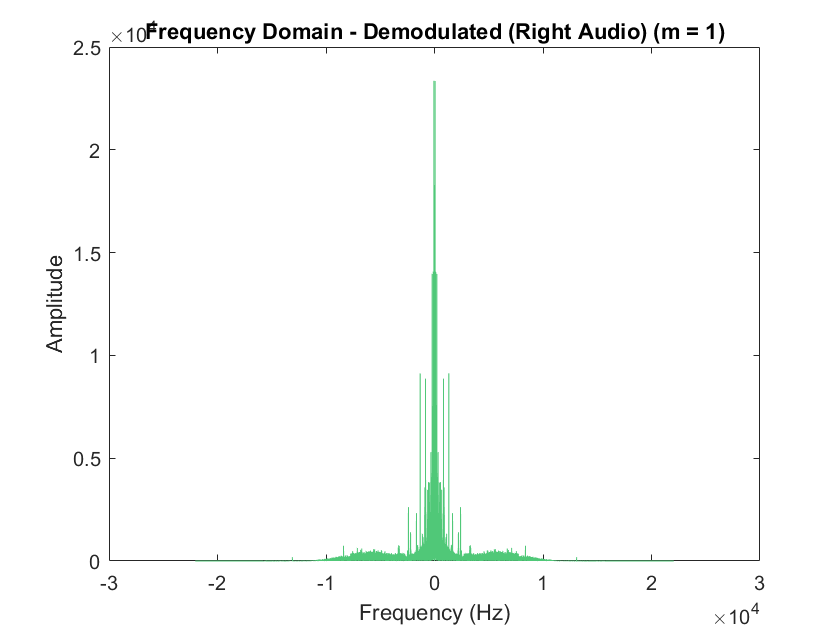

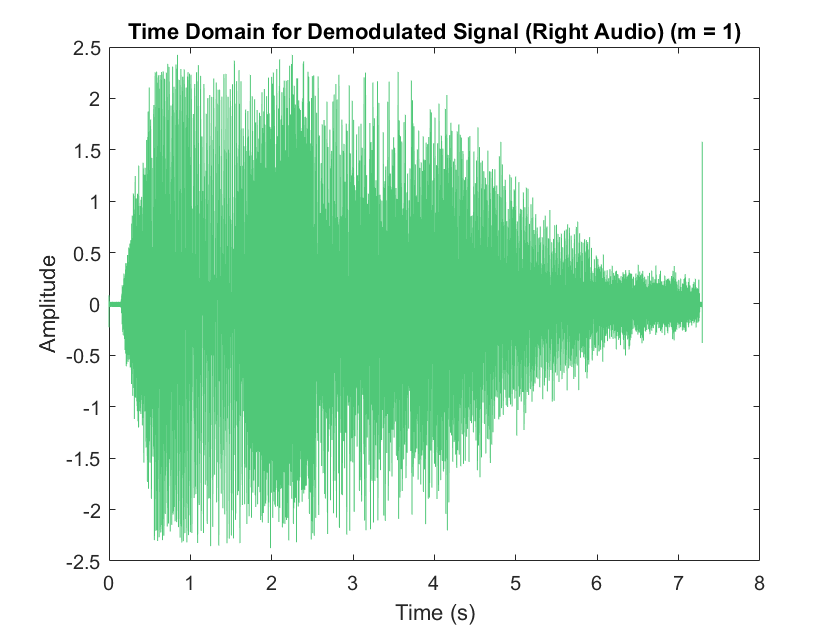

Playing demodulated audio (m = 1)


Audio Playback Completed.


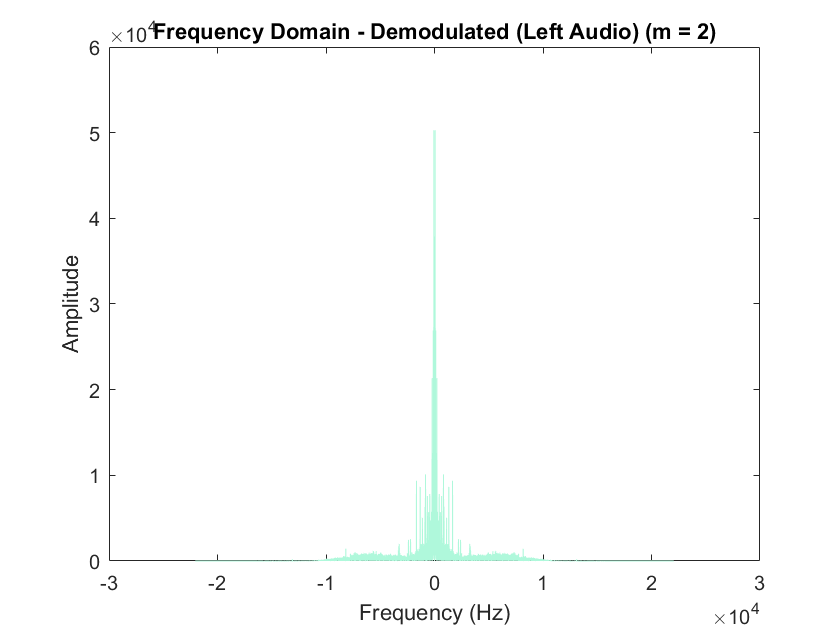

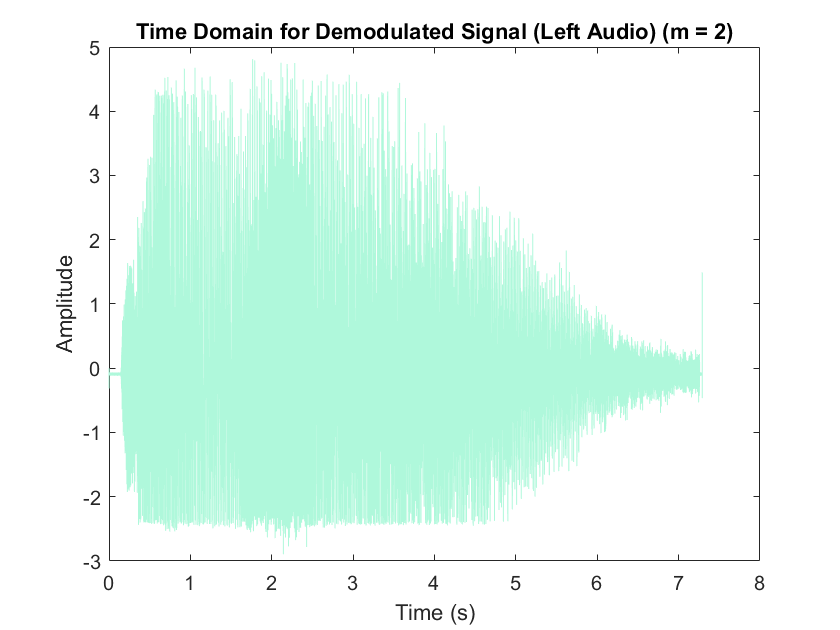

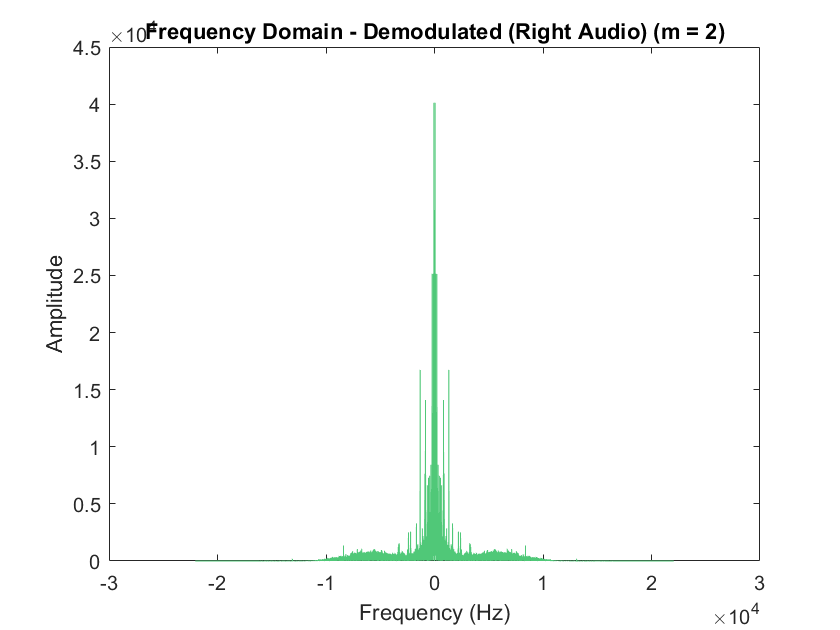

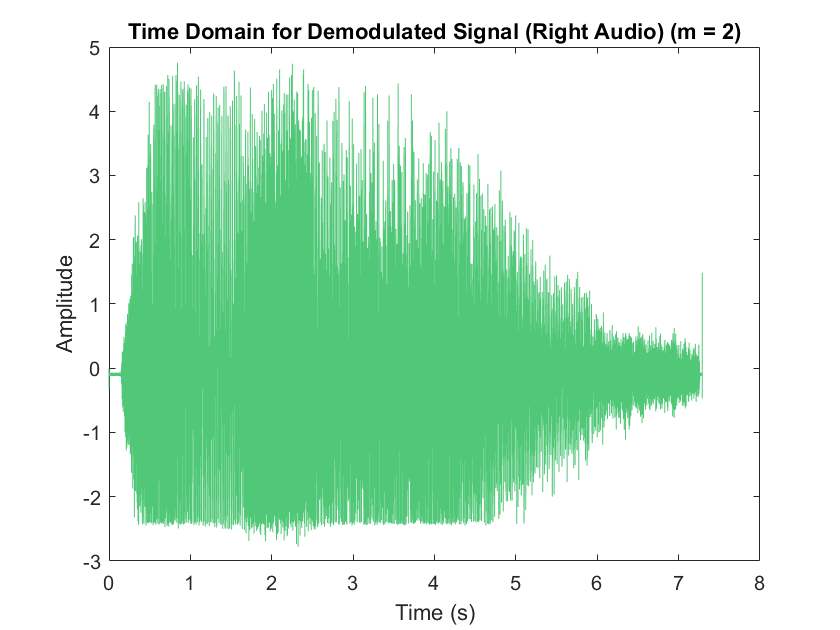

Playing demodulated audio (m = 2)


Audio Playback Completed.


% Design a low-pass Butterworth filter
f_cut = 10000; % Cutoff frequency in Hz
filterOrder = 5; % Filter order

% Design the low-pass Butterworth filter using butter
[b, a] = butter(filterOrder, f_cut / (fs / 2), 'low');

for i = 1:length(mu)
    % Generate the modulated signal with element-wise multiplication
    m = mu(i); % Modulation index
    y_modulated_l = (1 + m * l) .* c; % Use .* for element-wise multiplication
    y_modulated_r = (1 + m * r) .* c;

    % Perform incoherent demodulation
    y_demodulated_l = abs(y_modulated_l + 1i * hilbert(y_modulated_l));
    y_demodulated_r = abs(y_modulated_r + 1i * hilbert(y_modulated_r));

    % Remove DC offset
    y_demodulated_l = y_demodulated_l - mean(y_demodulated_l);
    y_demodulated_r = y_demodulated_r - mean(y_demodulated_r);

    % Apply the low-pass Butterworth filter to extract the message signal
    y_filtered_l = filtfilt(b, a, y_demodulated_l); % Use filtfilt for zero-phase filtering
    y_filtered_r = filtfilt(b, a, y_demodulated_r);

    % Combine the left and right audio channels
    demod(:, 1) = y_filtered_l;
    demod(:, 2) = y_filtered_r;

%     % Plot the original signal in the frequency domain (Left Audio)
%     L = fft(l);
%     f = (-length(L) / 2 : length(L) / 2 - 1) * fs / length(L);
% 
%     figure;
%     plot(f, abs(fftshift(L)), 'Color', '#aff8db');
%     title('Frequency Domain (Left Audio)');
%     xlabel('Frequency (Hz)');
%     ylabel('Amplitude');

    % Plot the demodulated signal in the frequency domain (Left Audio)
    Y_L = fft(demod(:, 1));
    f = (-length(Y_L) / 2 : length(Y_L) / 2 - 1) * fs / length(Y_L);

    figure;
    plot(f, abs(fftshift(Y_L)), 'Color', '#aff8db');
    title(['Frequency Domain - Demodulated (Left Audio) (m = ', num2str(m), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');

    % Plot the demodulated signal in the time domain (Left Audio)
    figure;
    plot(t, y_filtered_l, 'Color', '#aff8db');
    title(['Time Domain for Demodulated Signal (Left Audio) (m = ' num2str(mu(i)) ')']);
    xlabel('Time (s)');
    ylabel('Amplitude');

%     % Plot the original signal in the frequency domain (Right Audio)
%     R = fft(r);
%     f = (-length(R) / 2 : length(R) / 2 - 1) * fs / length(R);
% 
%     figure;
%     plot(f, abs(fftshift(R)), 'Color', '#50C878');
%     title('Frequency Domain (Right Audio)');
%     xlabel('Frequency (Hz)');
%     ylabel('Amplitude');

    % Plot the demodulated signal in the frequency domain (Left Audio)
    Y_R = fft(demod(:, 2));
    f = (-length(Y_R) / 2 : length(Y_R) / 2 - 1) * fs / length(Y_R);

    figure;
    plot(f, abs(fftshift(Y_R)), 'Color', '#50C878');
    title(['Frequency Domain - Demodulated (Right Audio) (m = ', num2str(m), ')']);
    xlabel('Frequency (Hz)');
    ylabel('Amplitude');

    % Plot the demodulated signal in the time domain (Right Audio)
    figure;
    plot(t, y_filtered_r, 'Color', '#50C878');
    title(['Time Domain for Demodulated Signal (Right Audio) (m = ' num2str(mu(i)) ')']);
    xlabel('Time (s)');
    ylabel('Amplitude');

    % Play the demodulated audio
    disp(['Playing demodulated audio (m = ', num2str(m), ')']); % Add a message to the console
    sound(demod, fs); % Play the demodulated and filtered audio using the 'sound' function
    pause(length(demod) / fs); % Pause to allow time for audio playback
    disp('Audio Playback Completed.'); % Display when the playback is completed
end